% data = [PASTE DATA HERE];
% speed_left = data(:,1)
% speed_right = data(:,2)
% time = linspace(0, 3000, 3000/20+1)'
% time = time(:, 1:141) / 1000; % shorten to match speed data, convert ms to s
% save("motor_calibration_data2", "speed_left", "speed_right", "time")

We are trying to solve for coefficients needed in M(s) motor control block, given as M(s) = V(s)/Vc(s), where V(s) is the velocity of each wheel, and Vc(s) is the velocity control signal coming from the PI controller K(s). 

The motor input signal we gave to collect this calibration data was a step input with a constant magnitude of 300. We could either consider Vc(t) to equal 300 in this case, or we could consider Vc(t) to equal 1 and 300 to be a baseline motor input which K will scale.

Either way, in the time domain V(s) is v(t) = 300*K*(1-exp(-t/tau)) for this case and we can fit the collected speed data for the right and left wheel to this function. Units of axes are speed [m/s] and time [s].

velocity_left = expFit(time, speed_left);

Unrecognized function or variable 'speed_left'.

K_left = velocity_left.K
tau_left = velocity_left.tau
K_left/300

velocity_right = expFit(time, speed_right);
K_right = velocity_right.K
tau_right = velocity_right.tau
K_right/300



gyro_angle = [
0.18
0.25
0.31
0.36
0.42
0.45
0.49
0.51
0.52
0.52
0.50
0.47
0.43
0.37
0.32
0.24
0.19
0.12
0.07
0.03
0.00
-0.01
-0.01
0.00
0.03
0.07
0.12
0.18
0.23
0.30
0.34
0.40
0.45
0.48
0.50
0.51
0.51
0.49
0.46
0.43
0.38
0.33
0.27
0.20
0.15
0.09
0.05
0.02
0.00
-0.00
0.01
0.03
0.07
0.11
0.16
0.21
0.28
0.34
0.38
0.43
0.47
0.48
0.49
0.49
0.47
0.45
0.41
0.37
0.31
0.27
0.21
0.15
0.11
0.07
0.04
0.03
0.03
0.03
0.05
0.08
0.12
0.16
0.22
0.26
0.32
0.37
0.40
0.44
0.46
0.47
0.46
0.45
0.43
0.40
0.36
0.32
0.26
0.22
0.17
0.13
0.10
0.07
0.05
0.05
0.05
0.07
0.09
0.13
0.16
0.21
0.26
0.29
0.34
0.38
0.41
0.43
0.44
0.44
0.43
0.42
0.39
0.35
0.32
0.27
0.22
0.19
0.15
0.11
0.09
0.07
0.07
0.07
0.08
0.10
0.13
0.17
0.20
0.24
0.29
0.32
0.36
0.38
0.41
0.42
0.42
0.42
0.40
0.38
0.34
0.31
0.27
0.23
0.19
0.16
0.12
]

gyro_angle =     0.1800
    0.2500
    0.3100
    0.3600
    0.4200
    0.4500
    0.4900
    0.5100
    0.5200
    0.5200





length(gyro_angle(:,1))

ans = 155

for i = 1:length(gyro_angle(:,1))
    if gyro_angle(i,1) < 0
        gyro_angle(i,1) = gyro_angle(i,1) + 3.14;
    end
%     if gyro_angle(i,1) > 0
%         gyro_angle(i,1) = gyro_angle(i,1) - 1.66;
%     end
end
gyro_angle

gyro_angle =     0.1800
    0.2500
    0.3100
    0.3600
    0.4200
    0.4500
    0.4900
    0.5100
    0.5200
    0.5200


 
time = linspace(0, 7750, 7750/50+1)'

time =      0
    50
   100
   150
   200
   250
   300
   350
   400
   450


time = time(1:155, :) / 1000; % shorten to match speed data, convert ms to s
save("gyro_calibration_data2", "gyro_angle", "time")


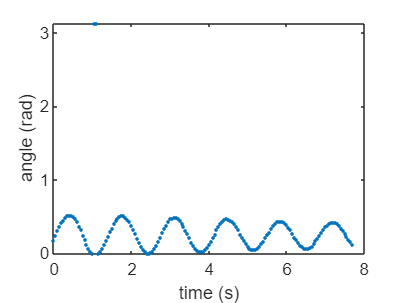

load("gyro_calibration_data2")

plot(time, gyro_angle, ".")
ylabel('angle (rad)')
xlabel('time (s)')


[angle, x] = findpeaks(gyro_angle, time)

angle =     0.5200
    3.1300
    0.5100
    0.4900
    0.4700
    0.4400
    0.4200


x =     0.4000
    1.0500
    1.7500
    3.1000
    4.4500
    5.8000
    7.1500



x_dif = x(2:end)-x(1:end-1)

x_dif =     0.6500
    0.7000
    1.3500
    1.3500
    1.3500
    1.3500



avg_period = mean(x_dif) % sec

avg_period = 1.1250


f = 1/avg_period % 1/sec

f = 0.8889


omega = 2 * pi * f % rad/sec

omega = 5.5851


% sqrt(g/l) = omega
g = 9.81 % m/s^2

g = 9.8100


effective_l = g/omega^2

effective_l = 0.3145

function [fitresult, gof] = expFit(time, speed)
%  Create a fit.
%
%  Data for 'velocity_fit' fit:
%      X Input: time
%      Y Output: speed
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.

%% Fit: 'velocity_fit'.
[xData, yData] = prepareCurveData( time, speed );

% Set up fittype and options.
ft = fittype( '300*K*(1-exp(-t/tau))', 'independent', 't', 'dependent', 'v' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.002 60/1000];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'velocity_right2_fit' );
h = plot( fitresult, xData, yData );
legend( h, 'speed_right2 vs. time', 'velocity_right2_fit', 'Location', 'NorthEast', 'Interpreter', 'none' );

% Label axes
xlabel( 'time', 'Interpreter', 'none' );
ylabel( 'speed_right2', 'Interpreter', 'none' );
grid on

end
